# Compare full 3D camera motion with parallax estimate

## Create a pbrt scene we can use

Using pbrt lets us get the highest-fidelity rendering

ieInit();
sceneLuminance = 200;
numRays = 128;
filmResolution = 256;
pbrtLensFile = true; 
sceneChoice = "Chess Set";
% apertureDiameter = 6;% in mm

% for legacy reasons, scenes don't have a uniform naming scheme,
% so we map the user's choice to the appropriate options
if strcmp(sceneChoice, "Cornell Box with Bunny")
    scenePath = 'Cornell_BoxBunnyChart';        
    sceneName = 'cornell box bunny chart';
elseif strcmp(sceneChoice, "Cornell Box Reference")
    scenePath = "cornell_box";
    sceneName = "cornell_box";
else
    scenePath = 'ChessSet';
    sceneName = 'chessSet';
end

pbrtCPScene = cpScene('pbrt', 'scenePath', scenePath, 'sceneName', sceneName, ...
    'resolution', [filmResolution filmResolution], ...
    'numRays', numRays, 'sceneLuminance', sceneLuminance, ...
    'lensFile','dgauss.22deg.6.0mm.json');

Read 9 materials and 3 textures..



% add a skymap and a light
pbrtCPScene.thisR.set('skymap','room.exr','rotation val',[-90 180 0]);

lightName = 'from camera';
ourLight = piLightCreate(lightName,...
                        'type','distant',...
                        'cameracoordinate', true);

pbrtCPScene.thisR.set('light', ourLight,'add');


## Create our sample camera

Just one module with a pre-made sensor and default optics.

% some timing code, just to see how fast we run...
setpref('ISET', 'benchmarkstart', cputime); 
setpref('ISET', 'tStart', tic);

% cpBurstCamera is a sub-class of cpCamera that implements simple HDR and Burst
% capture and processing
ourCamera = cpBurstCamera(); 

% We'll use a pre-defined sensor for our Camera Module, and let it use
% default optics for now. We can then assign the module to our camera:
sensor = sensorCreate('imx363'); 
ourCamera.cmodules(1) = cpCModule('sensor', sensor); % default

## Take Pictures using Auto, HDR, and Burst Intents

For the simplest case we ask our camera to take some pictures using pre-defined intents. By deault our camera assumes the 'Auto' intent. We also demonstrate 'Burst', which will capture more frames if the camera type we are using supports it. 'HDR' also fires a burst, but bracketed. Our default camera sums the frames in Burst mode, and chooses the highest non-saturated value at each pixel for HDR mode.

Elapsed time is 2.173518 seconds.
Put: wsl rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /mnt/c/iset/iset3d/local/ChessSet/ david@171.64.204.112:/home/david/iset/iset3d-v4/local/ChessSet/ ...
Done (1.96 sec)
Command: docker --context remote-mux exec -i  pbrt-gpu-Windows17718 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Rendered remotely in: 7.00 sec
Pull: wsl rsync -r  david@171.64.204.112:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/c/iset/iset3d/local/ChessSet/renderings ...
done (  1.57 sec)

Output file:  renderings/ChessSet.exr
*** Rendering time (ChessSet) was 12.2 sec ***

Put: wsl rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /mnt/c/iset/iset3d/local/ChessSet/ david@171.64.204.112:/home/david/iset/iset3d-v4/local/ChessSet/ ...
Done (2.06 sec)
Command: docker --context remote-mux exec -i  pbrt-gpu-Windows17718 sh -c "cd /iset/iset3d-v4/local/ChessSe

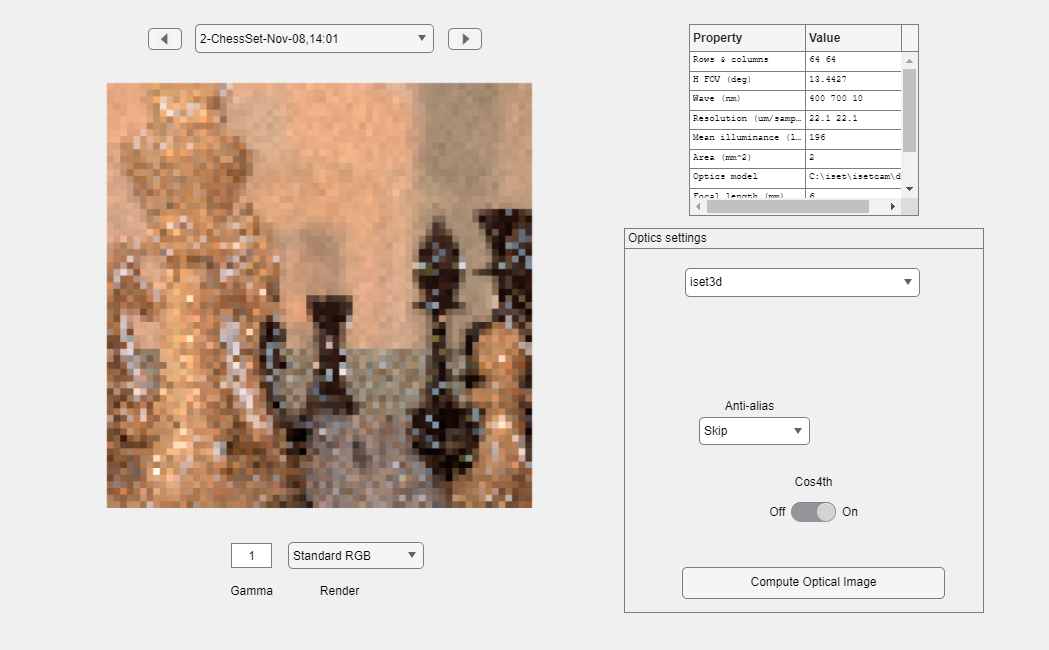

autoImage = ourCamera.TakePicture(pbrtCPScene, 'Auto',...
    'imageName','Auto Mode no motion', 'insensorIP',false); 

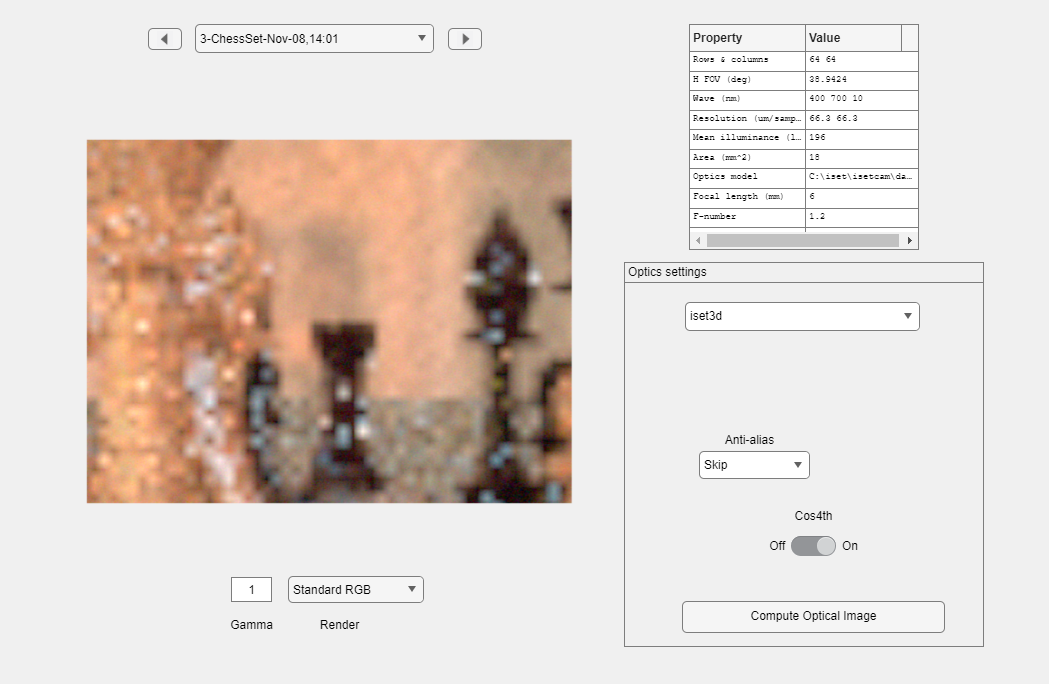

Elapsed time is 2.396246 seconds.
Put: wsl rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /mnt/c/iset/iset3d/local/ChessSet/ david@171.64.204.112:/home/david/iset/iset3d-v4/local/ChessSet/ ...
Done (1.86 sec)
Command: docker --context remote-mux exec -i  pbrt-gpu-Windows17718 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Rendered remotely in: 7.75 sec
Pull: wsl rsync -r  david@171.64.204.112:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/c/iset/iset3d/local/ChessSet/renderings ...
done (  1.32 sec)

Output file:  renderings/ChessSet.exr
*** Rendering time (ChessSet) was 12.6 sec ***



Put: wsl rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /mnt/c/iset/iset3d/local/ChessSet/ david@171.64.204.112:/home/david/iset/iset3d-v4/local/ChessSet/ ...
Done (2.08 sec)
Command: docker --context remote-mux exec -i  pbrt-gpu-Windows17718 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Rendered remotely in: 3.59 sec
Pull: wsl rsync -r  david@171.64.204.112:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/c/iset/iset3d/local/ChessSet/renderings ...
done (  1.54 sec)

Output file:  renderings/ChessSet.exr
*** Rendering time (ChessSet) was 8.7 sec ***

Elapsed time is 2.030519 seconds.
Put: wsl rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /mnt/c/iset/iset3d/local/ChessSet/ david@171.64.204.112:/home/david/iset/iset3d-v4/local/ChessSet/ ...
Done (1.88 sec)
Command: docker --context remote-mux exec -i  pbrt-gpu-Windows17718 sh -c "cd /iset/iset3d-v4/local/ChessSet

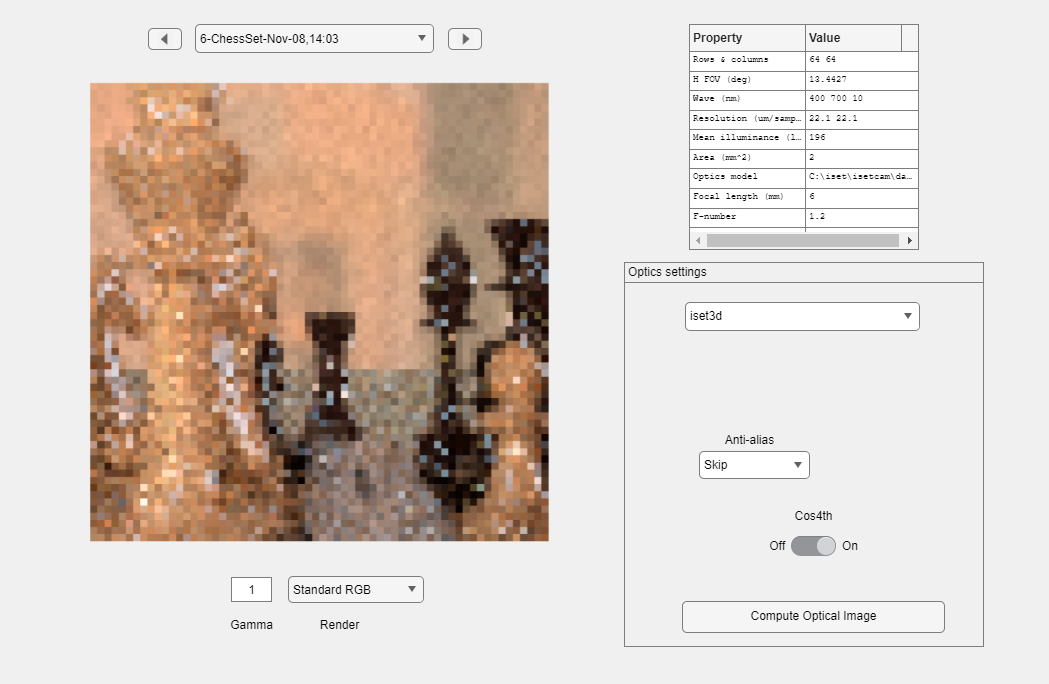

imshow(autoImage);

% hdrSensorImage = ourCamera.TakePicture(pbrtCPScene, 'HDR',...
%    'numHDRFrames', 3,'imageName','HDR in sensor no motion', ...
%    'insensorIP', true);

burstSensorImage = ourCamera.TakePicture(pbrtCPScene, 'Burst',...
    'numBurstFrames', 3, 'imageName','Burst in Sensor',...
    'insensorIP',true);

% cpCompareImages(hdrSensorImage, burstSensorImage, 'HDR vs Burst with no moion');


## Now we add a small amount of camera motion

Combining multiple frames into a single image can either be done at the sensor level, or a higher-level in the ISP. At the sensor level the default strategies implemented by ISETCam are to compute a normalized sum of the individual frames for Burst mode, and select the image with the most signal at each pixel for HDR. Once there is camera motion, though, those algorithms create errors in registration.

pbrtCPScene.cameraMotion = {{'unused', [.002, 0, 0], [0, 0, 0]}}; % first tuple is translation, second is rotation

hdrMotionImage = ourCamera.TakePicture(pbrtCPScene, 'HDR',...
    'numHDRFrames', 3,'imageName','HDR in ISP with Motion', ...
    'insensorIP', true);

Elapsed time is 1.725423 seconds.
Put: wsl rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /mnt/c/iset/iset3d/local/ChessSet/ david@171.64.204.112:/home/david/iset/iset3d-v4/local/ChessSet/ ...
Done (2.06 sec)
Command: docker --context remote-mux exec -i  pbrt-gpu-Windows17718 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Rendered remotely in: 7.97 sec
Pull: wsl rsync -r  david@171.64.204.112:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/c/iset/iset3d/local/ChessSet/renderings ...
done (  1.43 sec)

Output file:  renderings/ChessSet.exr
*** Rendering time (ChessSet) was 13.2 sec ***

Put: wsl rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /mnt/c/iset/iset3d/local/ChessSet/ david@171.64.204.112:/home/david/iset/iset3d-v4/local/ChessSet/ ...
Done (1.96 sec)
Command: docker --context remote-mux exec -i  pbrt-gpu-Windows17718 sh -c "cd /iset/iset3d-v4/local/ChessSe

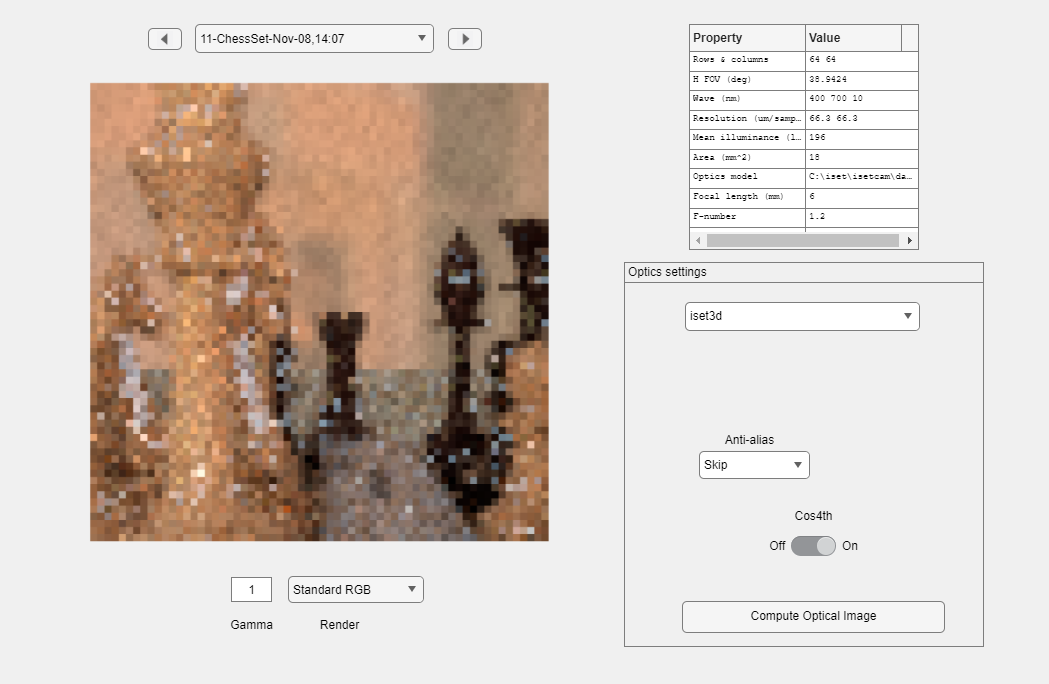

Elapsed time is 1.912881 seconds.
Put: wsl rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /mnt/c/iset/iset3d/local/ChessSet/ david@171.64.204.112:/home/david/iset/iset3d-v4/local/ChessSet/ ...
Done (1.86 sec)
Command: docker --context remote-mux exec -i  pbrt-gpu-Windows17718 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Rendered remotely in: 8.51 sec
Pull: wsl rsync -r  david@171.64.204.112:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/c/iset/iset3d/local/ChessSet/renderings ...
done (  1.55 sec)

Output file:  renderings/ChessSet.exr
*** Rendering time (ChessSet) was 13.3 sec ***



Put: wsl rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /mnt/c/iset/iset3d/local/ChessSet/ david@171.64.204.112:/home/david/iset/iset3d-v4/local/ChessSet/ ...
Done (1.86 sec)
Command: docker --context remote-mux exec -i  pbrt-gpu-Windows17718 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Rendered remotely in: 3.24 sec
Pull: wsl rsync -r  david@171.64.204.112:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/c/iset/iset3d/local/ChessSet/renderings ...
done (  1.45 sec)

Output file:  renderings/ChessSet.exr
*** Rendering time (ChessSet) was 8.0 sec ***

Elapsed time is 2.028284 seconds.
Put: wsl rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /mnt/c/iset/iset3d/local/ChessSet/ david@171.64.204.112:/home/david/iset/iset3d-v4/local/ChessSet/ ...
Done (1.98 sec)
Command: docker --context remote-mux exec -i  pbrt-gpu-Windows17718 sh -c "cd /iset/iset3d-v4/local/ChessSet

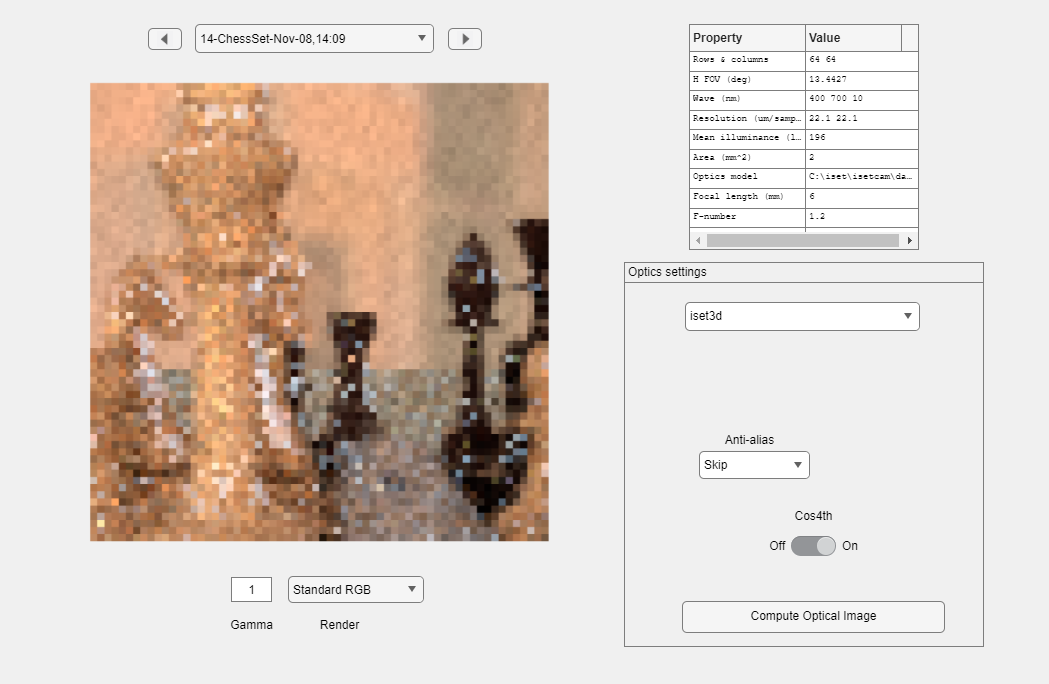

% cpCompareImages(hdrSensorImage, hdrMotionImage, 'In sensor HDR without and with motion');

burstMotionImage = ourCamera.TakePicture(pbrtCPScene, 'Burst',...
    'numBurstFrames', 3, 'imageName','Burst in ISP with Motion',...
    'insensorIP',false);

## Motion Simulation Using Parallax

Re-rendering the optical image for each frame in a scene that includes motion is computationally-expensive. So we have implemented an estimation using the depth map from our OI to create a shifted OI where the amount of the shift is based on the inverse of object depth.

% define our camera motion
motionAmounts = {[0 .1], [0 .2]}; % Assumes 3-frames 
% Create baseline OI
oi = piRender(pbrtCPScene.thisR);

Put: wsl rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /mnt/c/iset/iset3d/local/ChessSet/ david@171.64.204.112:/home/david/iset/iset3d-v4/local/ChessSet/ ...
Done (2.07 sec)
Command: docker --context remote-mux exec -i  pbrt-gpu-Windows17718 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Rendered remotely in: 6.26 sec
Pull: wsl rsync -r  david@171.64.204.112:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/c/iset/iset3d/local/ChessSet/renderings ...
done (  1.65 sec)

Output file:  renderings/ChessSet.exr
*** Rendering time (ChessSet) was 11.6 sec ***



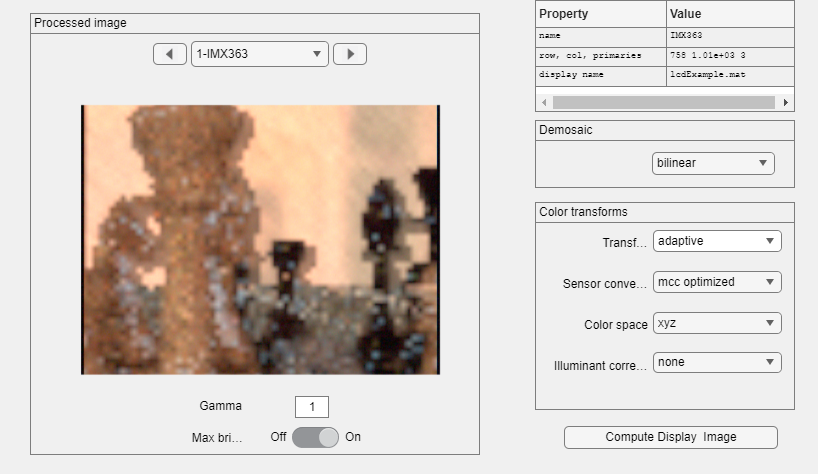

oiBurst = oiCameraMotion(oi,'amount',motionAmounts);
aeMethod = 'specular';
aeLevels = .8;
aeTime = autoExposure(oi,sensor, aeLevels, aeMethod);
burstFrames = 3;
burstTimes = repelem(aeTime/burstFrames, burstFrames);

hFOV = oiGet(oi,'hfov');
sensor = sensorSetSizeToFOV(sensor,hFOV,oi);

sensor_burst = sensorSet(sensor,'exp time',burstTimes);
sensor_burst = sensorSet(sensor_burst, 'exposure method', 'burst');
sensor_burst = sensorCompute(sensor_burst,oiBurst);

ip = ipCreate();
ip = ipCompute(ip,sensor_burst);
ipWindow(ip);

## Print out some timing stats

Just for human consumption

tTotal = toc(getpref('ISET','tStart'));
afterTime = cputime;
beforeTime = getpref('ISET', 'benchmarkstart', 0);
glData = opengl('data');
disp(strcat("cpCompare ran  on: ", glData.Vendor, " ", glData.Renderer, "with driver version: ", glData.Version)); 

cpCompare ran  on: Intel Intel(R) Iris(R) Xe Graphicswith driver version: 4.5.0 - Build 31.0.101.3675


disp(strcat("cpCompare ran  in: ", string(afterTime - beforeTime), " seconds of CPU time."));

cpCompare ran  in: 353.875 seconds of CPU time.


disp(strcat("cpCompare ran  in: ", string(tTotal), " total seconds."));

cpCompare ran  in: 601.9397 total seconds.
